# Problem 1

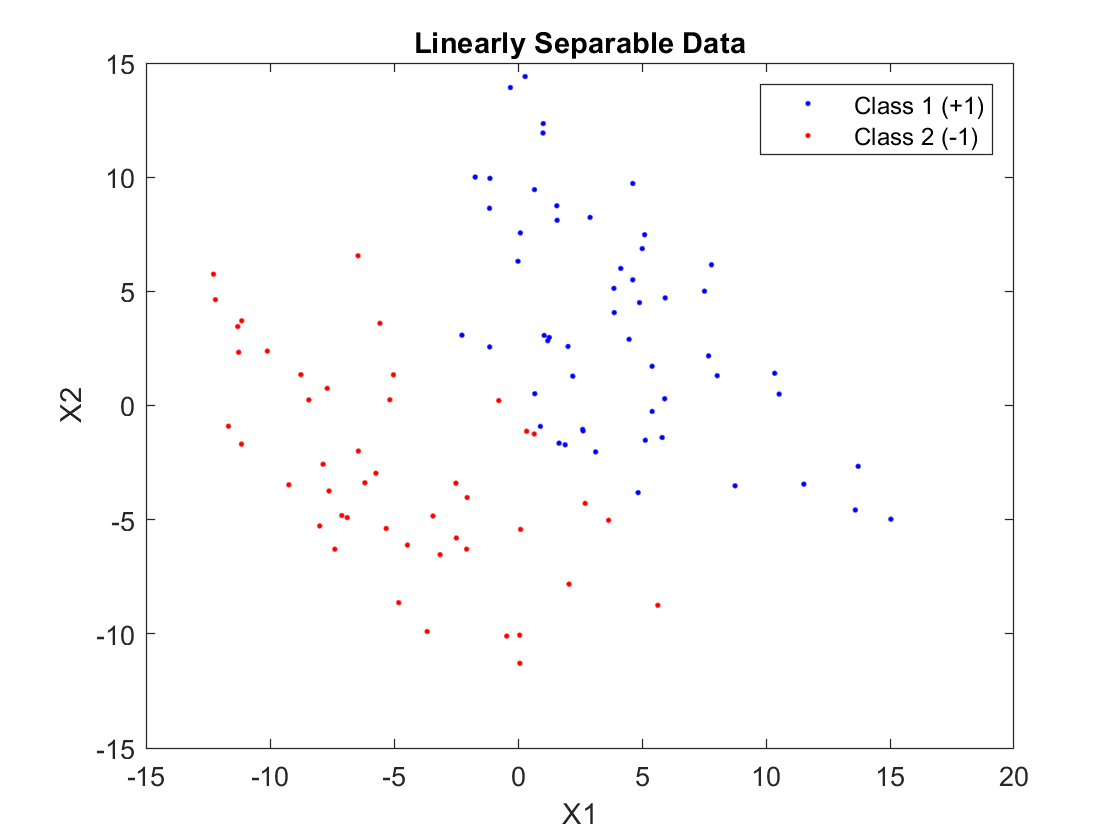

% Linearly Separable Data
N = 100;
dim = 2;
% X = [x0; x1; x2]
X =  zeros(dim,N);
X(1:dim,:) = [-10 + (10+10)*rand(dim,N)];
% hyperplane = [a0; a1; a2]
H = [rand(dim,1)];
xP = X-(H'*X)/(norm(H)^2).*H;
r = [-10 + (10+10)*rand(1,N)];
x = xP + r.*(H/norm(H));
target = sign(H'*x);
pos = target > 0;
neg = target < 0;
x1 = linspace(-15,15);
figure()
%p = [-H(2)/H(3) -H(1)/H(3)];
%y1 = polyval(p,x1);
%subplot(3,1,1)
plot(x(1,pos),x(2,pos),'b.',x(1,neg),x(2,neg),'r.')
xlabel('X1')
ylabel('X2')
title('Linearly Separable Data')
legend('Class 1 (+1)','Class 2 (-1)')
saveas(gcf,'P1\Dataset1.jpg')

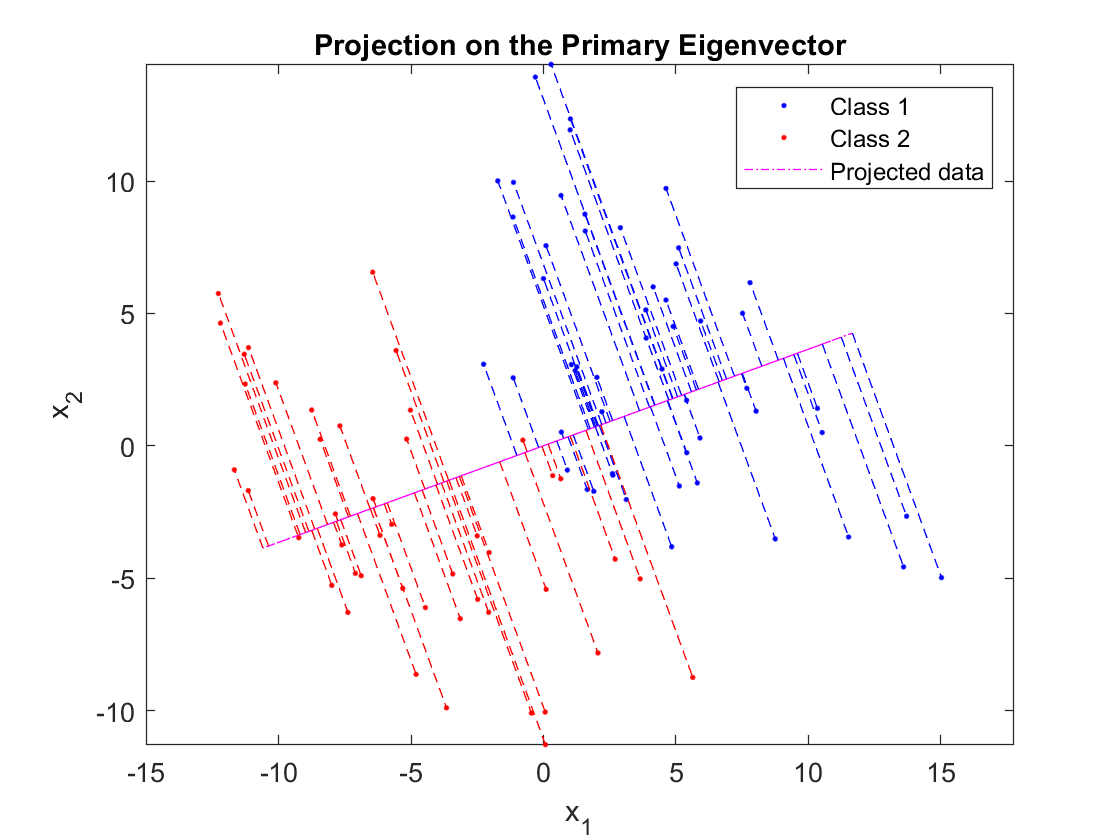

type = "Secondary"

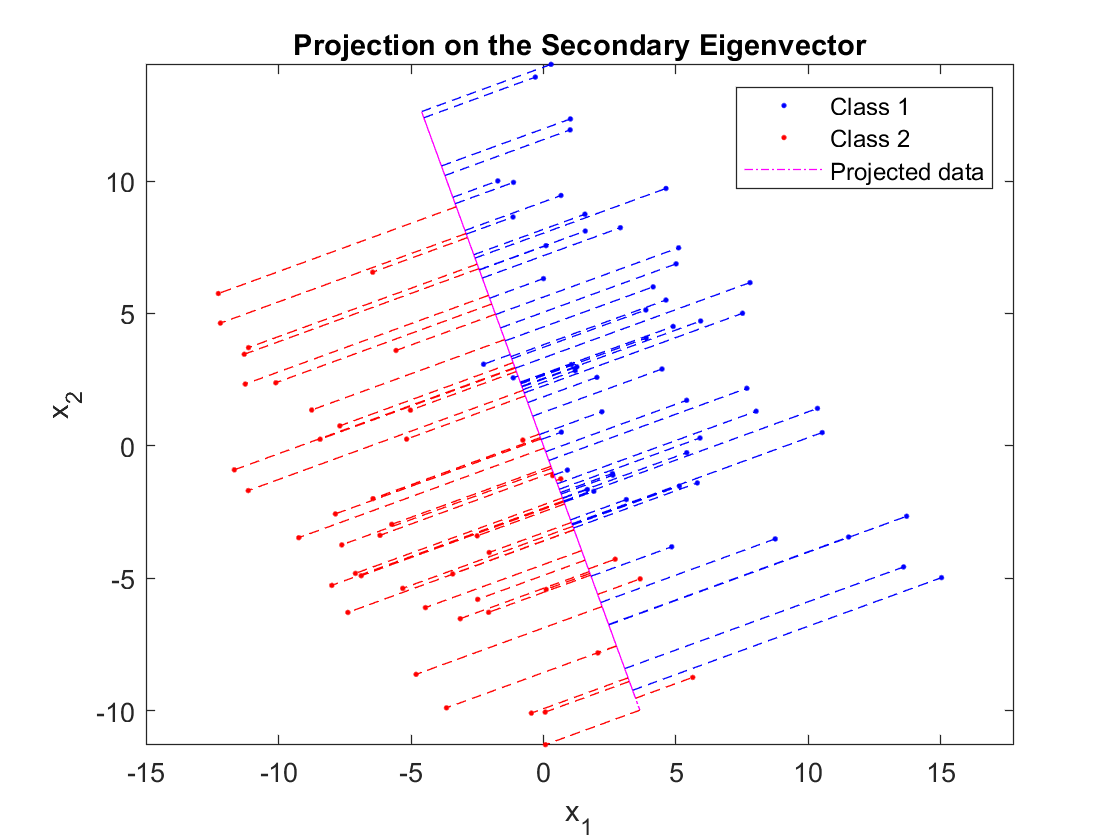

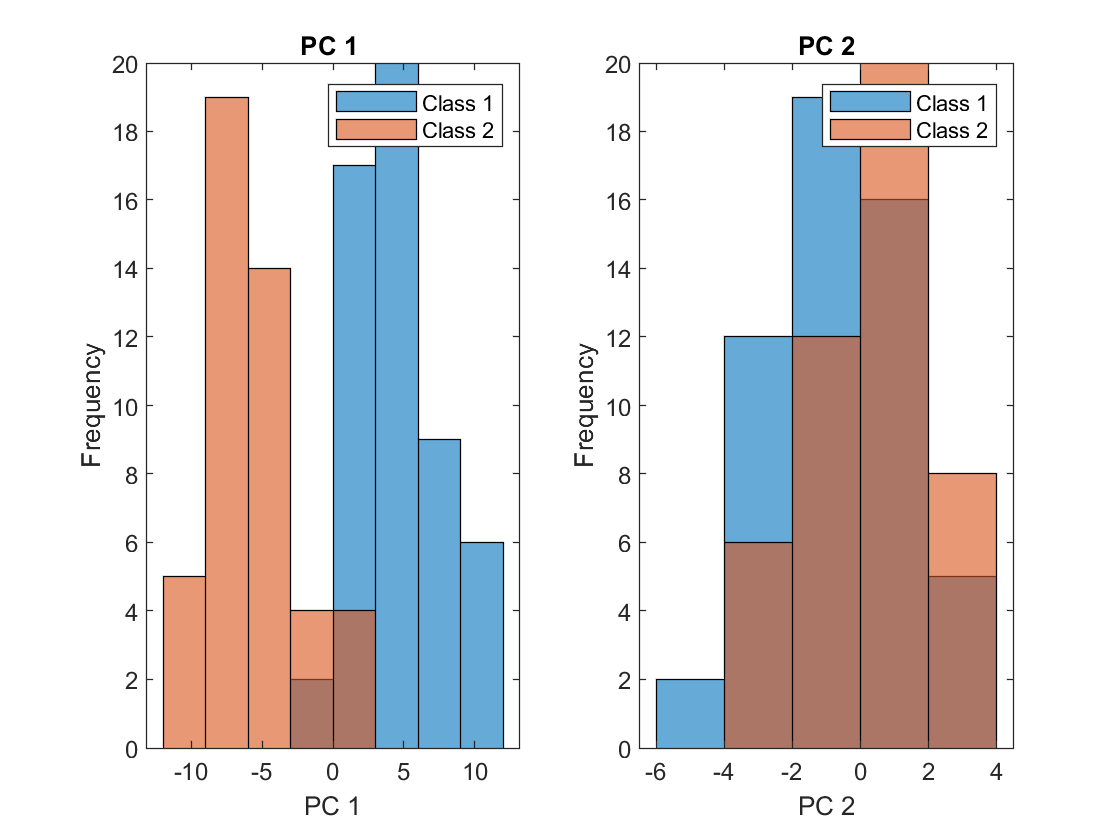

Xin = x';
Xin2 = Xin - mean(Xin);
covXin = cov(Xin2);
[eigXin, eigVal,W] = eig(covXin);
[B I]=sort(diag(eigVal),'descend');
for j = 1:length(I)
    ind = I(j);
    tr = Xin*eigXin(:,ind)*eigXin(:,ind)';

    figure;
    plot(Xin(pos,1),Xin(pos,2),'b.',Xin(neg,1),Xin(neg,2),'r.');
    hold on;
    plot(tr(:,1),tr(:,2),'m-.');
    hold on;
    for i=1:size(tr,1)
        if pos(i) == 1
          line([tr(i,1),Xin(i,1)], [tr(i,2),Xin(i,2)],'Color','blue','LineStyle','--');
        else
          line([tr(i,1),Xin(i,1)], [tr(i,2),Xin(i,2)],'Color','red','LineStyle','--');  
        end
      hold on;
    end
    if j == 1
        type = "Primary";
    elseif j == 2
        type = "Secondary"
    end
    title('Projection on the '+type+' Eigenvector');
    xlabel('x_1'); ylabel('x_2');
    legend('Class 1', 'Class 2','Projected data');
    axis equal;
    saveas(gcf,'P1\PCA_Proj_'+type+'.jpg')
    if j == 2
        figure()
        pc1 = Xin*eigXin(:,I(1))*eigXin(:,I(1))';
        subplot(1,2,1)
        histogram(pc1(pos)); hold on;histogram(pc1(neg));
        title('PC 1 ')
        xlabel('PC 1')
        ylabel('Frequency')
        legend('Class 1','Class 2')
        
        pc2 = Xin*eigXin(:,I(2))*eigXin(:,I(2))';
        subplot(1,2,2)
        histogram(pc2(pos)); hold on;histogram(pc2(neg));
        title('PC 2')
        xlabel('PC 2')
        ylabel('Frequency')
        legend('Class 1','Class 2')
        saveas(gcf,'P1\PCA_Histogram.jpg')
    end
end

## LDA

% Get mean and cov matrix of each class

% Positive Class
Xp = Xin(pos,:);
muP = mean(Xp);
covP = cov(Xp);
nP = length(Xp);
% Negative Class
Xn = Xin(neg,:);
muN = mean(Xn);
covN = cov(Xn);
nN = length(Xn);
% Scatter within class Sw = S1 + S2
sP = (Xp - muP)';sN = (Xn - muN)';
SP2 = (1/nP).*(sP*sP'); SN2 = (1/nN).*(sN*sN');
Sw = SP2 + SN2;
Sb = (muP-muN)'*(muP-muN);
w = inv(Sw)*(muP-muN)';
[V,D] = eig(inv(Sw)*Sb);
Wproj = V(:,2);
tr = (Wproj'*Xin')'*Wproj'/(norm(Wproj));


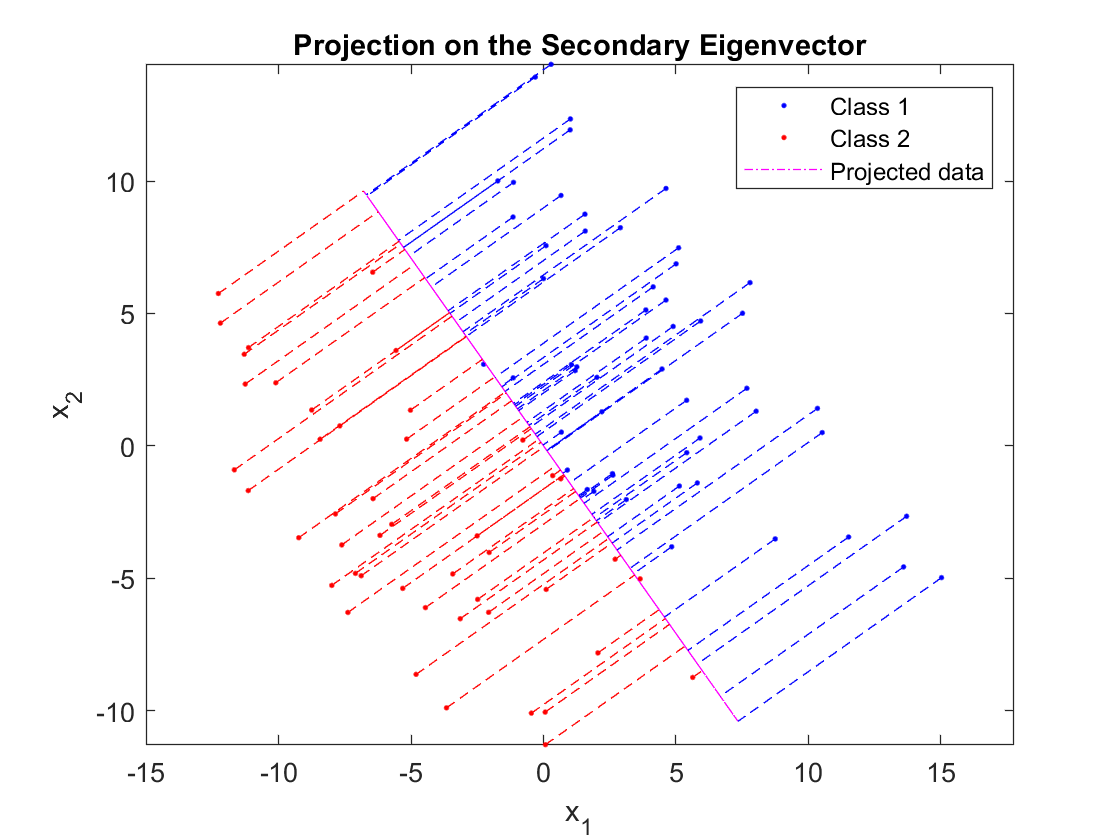

figure;
plot(Xin(pos,1),Xin(pos,2),'b.',Xin(neg,1),Xin(neg,2),'r.');
hold on;
plot(tr(:,1),tr(:,2),'m-.');
hold on;
for i=1:size(tr,1)
    if pos(i) == 1
      line([Xin(i,1),tr(i,1)], [Xin(i,2),tr(i,2)],'Color','blue','LineStyle','--');
    else
      line([Xin(i,1),tr(i,1)], [Xin(i,2),tr(i,2)],'Color','red','LineStyle','--');  
    end
  hold on;
end
type = "Secondary";
title('Projection on the ' +type+' Eigenvector');
xlabel('x_1'); ylabel('x_2');
legend('Class 1', 'Class 2','Projected data');
axis equal;
saveas(gcf,'P1\LDA_Proj_'+type+'.jpg')

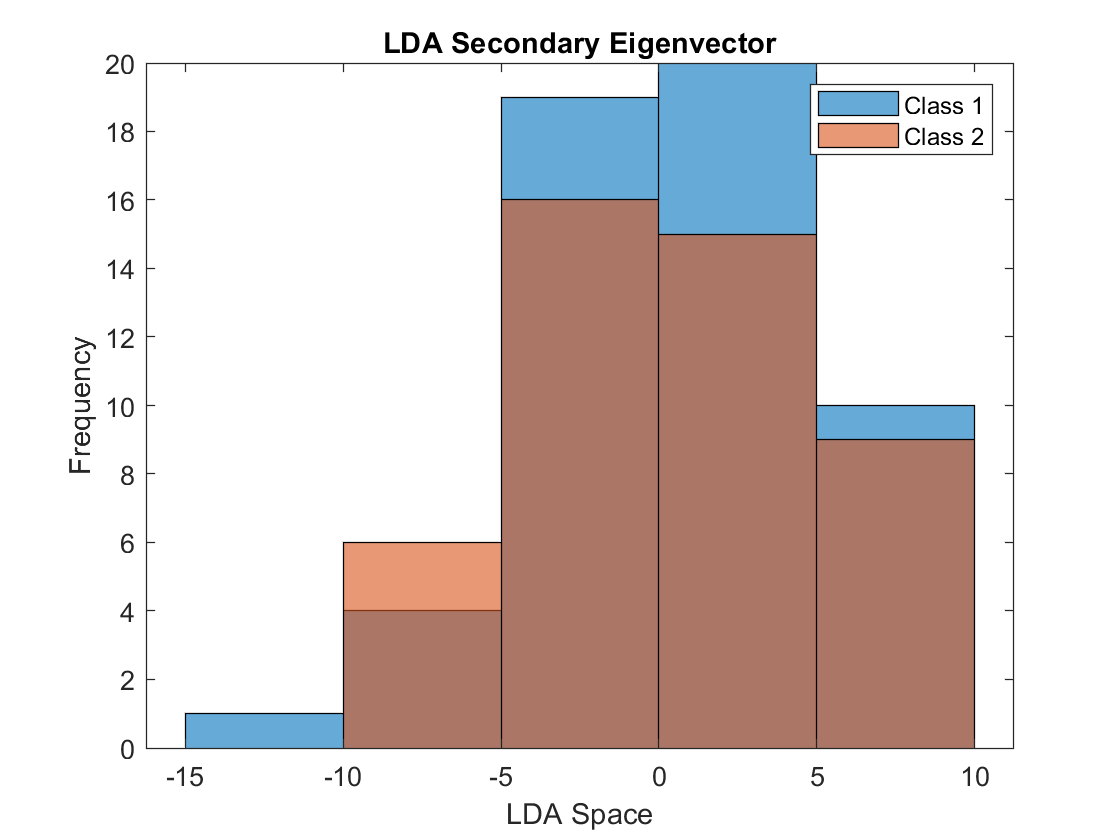


figure()

histogram(tr(pos,2))
hold on
histogram(tr(neg,2))
title('LDA '+type+' Eigenvector')
xlabel('LDA Space')
ylabel('Frequency')
legend('Class 1','Class 2')
saveas(gcf,'P1\LDA_Histogram_'+type+'.jpg')

## Dataset 2

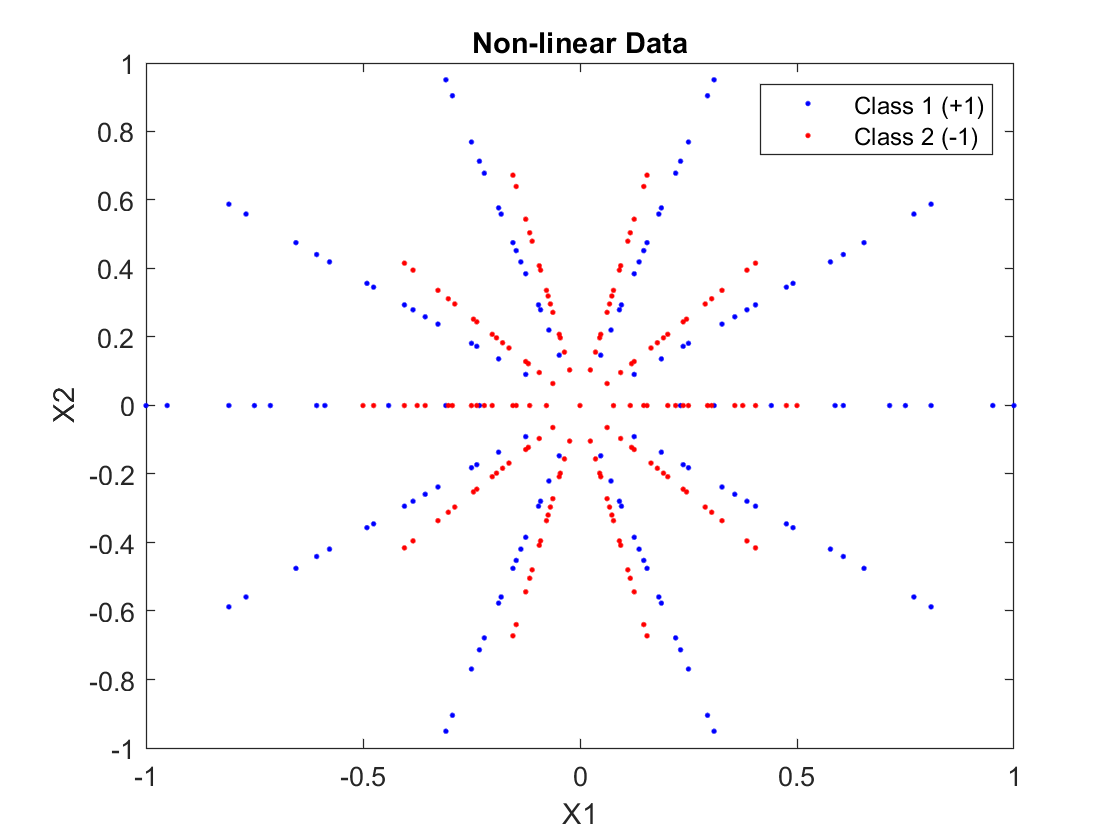

figure
[X,Y,Z] = sphere(10);
x = [0.5*X(:); 0.75*X(:); X(:)];
y = [0.5*Y(:); 0.75*Y(:); Y(:)];
x1 = x; x2 = x*cosd(60); y1 = y; y2=y*sind(45);
X = [vertcat(x1,x2),vertcat(y1,y2)];
pos = 1:length(x1);
neg = length(pos)+1:length(X);
plot(x1,y1,'b.',x2,y2,'r.')
xlabel('X1')
ylabel('X2')
title('Non-linear Data')
legend('Class 1 (+1)','Class 2 (-1)')
saveas(gcf,'P1\Dataset2.jpg')

Xin = X;
Xin2 = Xin - mean(Xin);
covXin = cov(Xin2);
[eigXin, eigVal,W] = eig(covXin);
[B I]=sort(diag(eigVal),'descend');

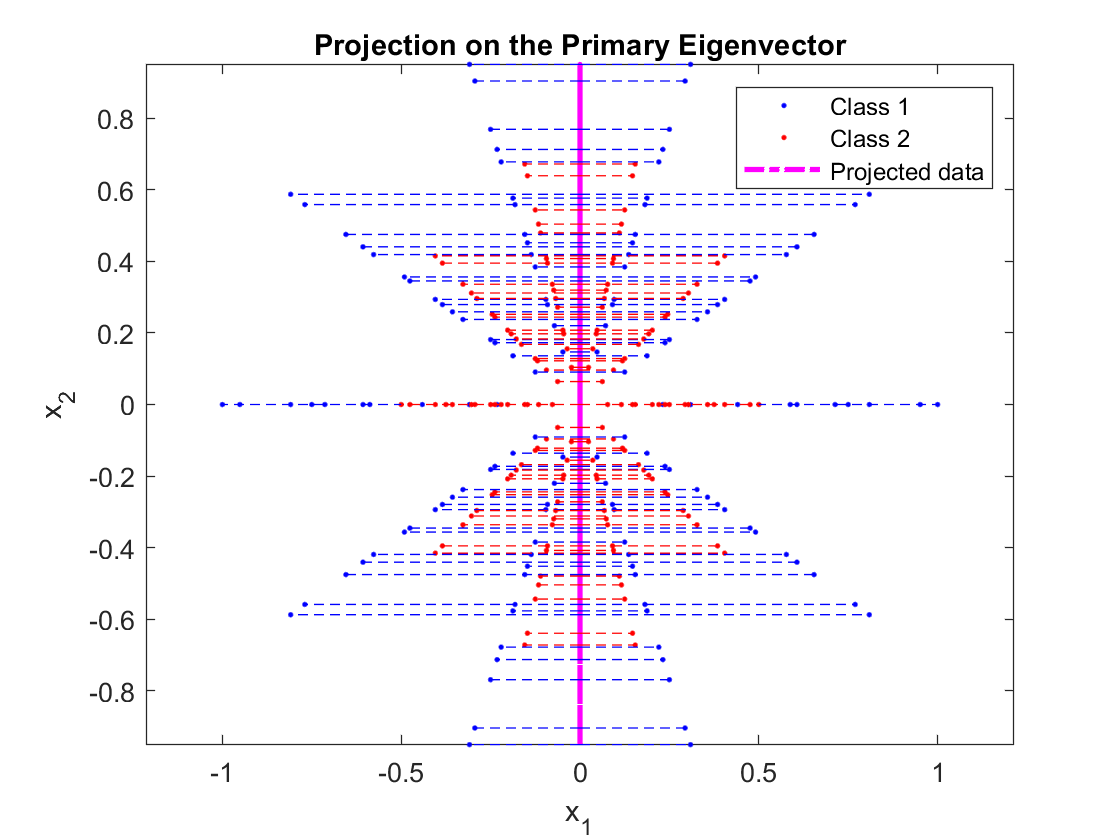

type = "Secondary"

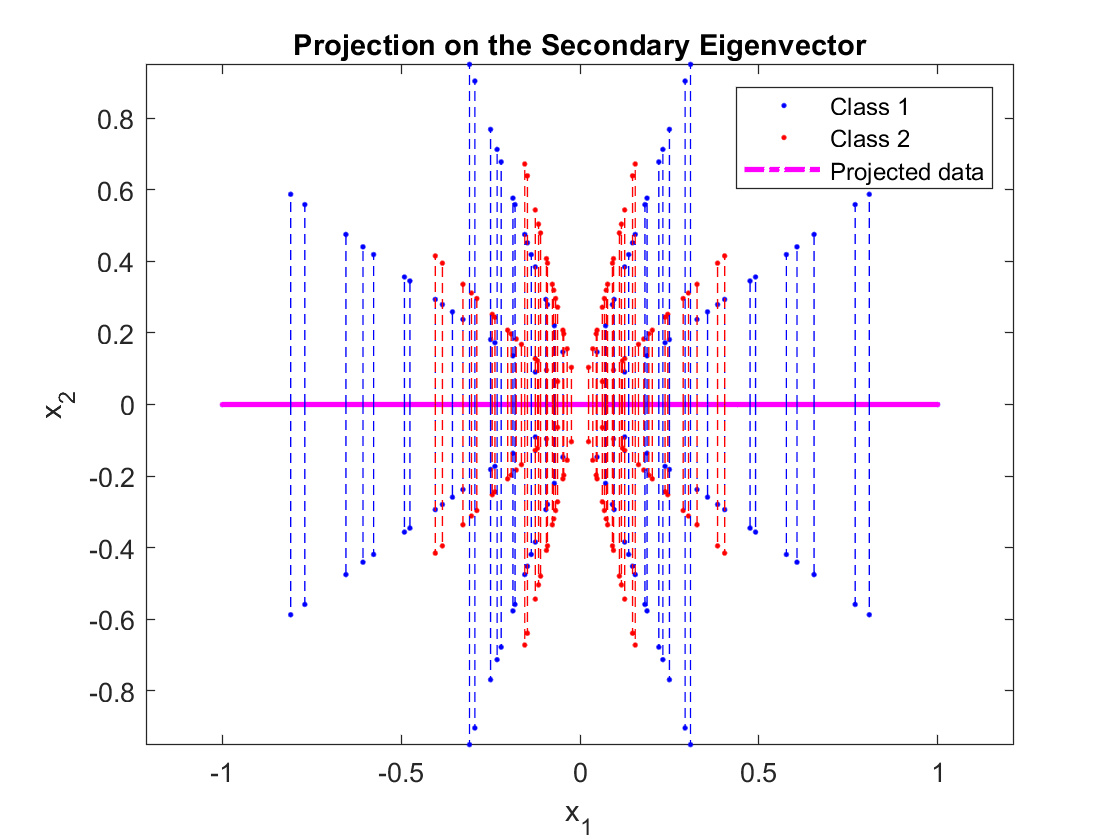

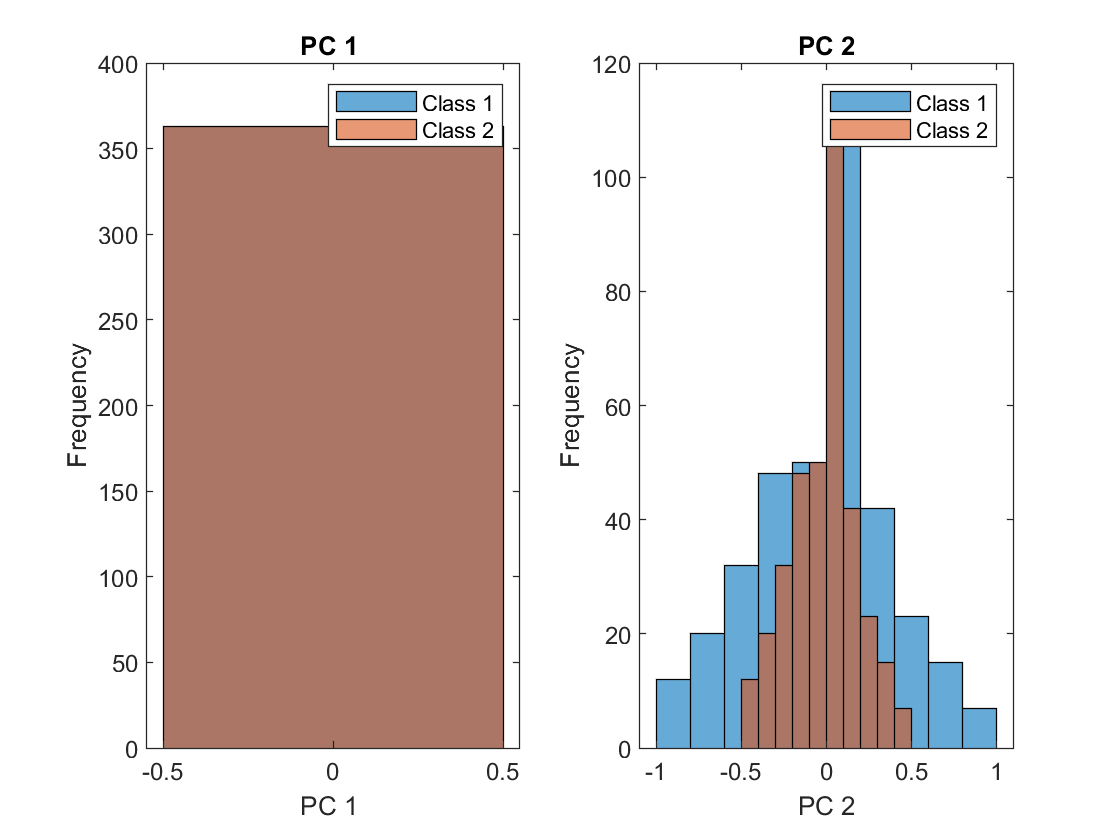

for j = 1:length(I)
    ind = I(j);
    tr = Xin*eigXin(:,ind)*eigXin(:,ind)';

    figure;
    plot(Xin(pos,1),Xin(pos,2),'b.',Xin(neg,1),Xin(neg,2),'r.');
    hold on;
    plot(tr(:,1),tr(:,2),'m-.','LineWidth',2);
    hold on;
    for i=1:size(tr,1)
        if i <= length(pos)
          line([tr(i,1),Xin(i,1)], [tr(i,2),Xin(i,2)],'Color','blue','LineStyle','--');
        else
          line([tr(i,1),Xin(i,1)], [tr(i,2),Xin(i,2)],'Color','red','LineStyle','--');  
        end
      hold on;
    end
    if j == 1
        type = "Primary";
    elseif j == 2
        type = "Secondary"
    end
    title('Projection on the '+type+' Eigenvector');
    xlabel('x_1'); ylabel('x_2');
    legend('Class 1', 'Class 2','Projected data');
    axis equal;
    saveas(gcf,'P1\PCA2_Proj_'+type+'.jpg')
    if j == 2
        figure()
        pc1 = Xin*eigXin(:,I(1))*eigXin(:,I(1))';
        subplot(1,2,1)
        histogram(pc1(pos)); hold on;histogram(pc1(neg));
        title('PC 1 ')
        xlabel('PC 1 ')
        ylabel('Frequency')
        legend('Class 1','Class 2')
        
        pc2 = Xin*eigXin(:,I(2))*eigXin(:,I(2))';
        subplot(1,2,2)
        histogram(pc2(pos)); hold on;histogram(pc2(neg));
        title('PC 2')
        xlabel('PC 2')
        ylabel('Frequency')
        legend('Class 1','Class 2')
        saveas(gcf,'P1\PCA2_Histogram.jpg')
    end
end

## LDA

% Get mean and cov matrix of each class

% Positive Class
Xp = Xin(pos,:);
muP = mean(Xp);
covP = cov(Xp);
nP = length(Xp);
% Negative Class
Xn = Xin(neg,:);
muN = mean(Xn);
covN = cov(Xn);
nN = length(Xn);
% Scatter within class Sw = S1 + S2
sP = (Xp - muP)';sN = (Xn - muN)';
SP2 = (1/nP).*(sP*sP'); SN2 = (1/nN).*(sN*sN');
Sw = SP2 + SN2;
Sb = (muP-muN)'*(muP-muN);
w = inv(Sw)*(muP-muN)';
[V,D] = eig(inv(Sw)*Sb);
Wproj = V(:,2);
tr = (Wproj'*Xin')'*Wproj'/(norm(Wproj));


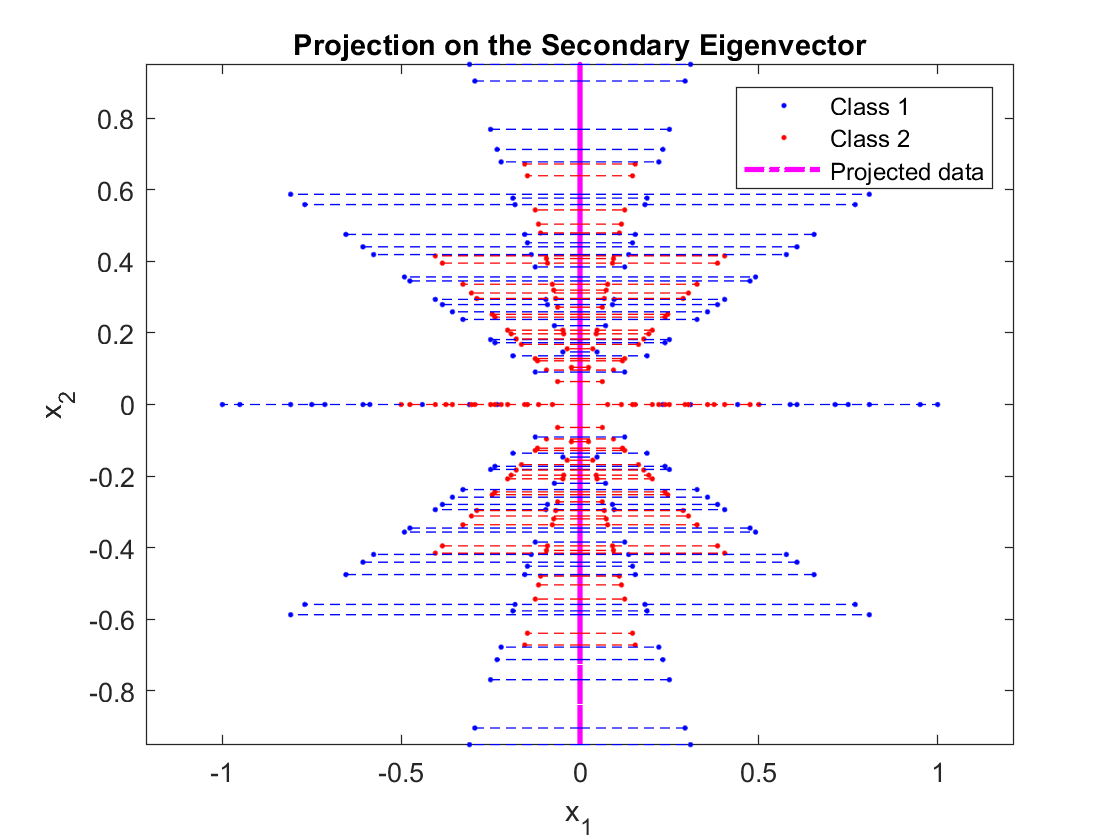

figure;
plot(Xin(pos,1),Xin(pos,2),'b.',Xin(neg,1),Xin(neg,2),'r.');
hold on;
plot(tr(:,1),tr(:,2),'m-.','LineWidth',2);
hold on;
for i=1:size(tr,1)
     if i <= length(pos)
          line([tr(i,1),Xin(i,1)], [tr(i,2),Xin(i,2)],'Color','blue','LineStyle','--');
        else
          line([tr(i,1),Xin(i,1)], [tr(i,2),Xin(i,2)],'Color','red','LineStyle','--');  
     end
  hold on;
end
type = "Secondary";
title('Projection on the ' +type+' Eigenvector');
xlabel('x_1'); ylabel('x_2');
legend('Class 1', 'Class 2','Projected data');
axis equal;
saveas(gcf,'P1\LDA2_Proj_'+type+'.jpg')

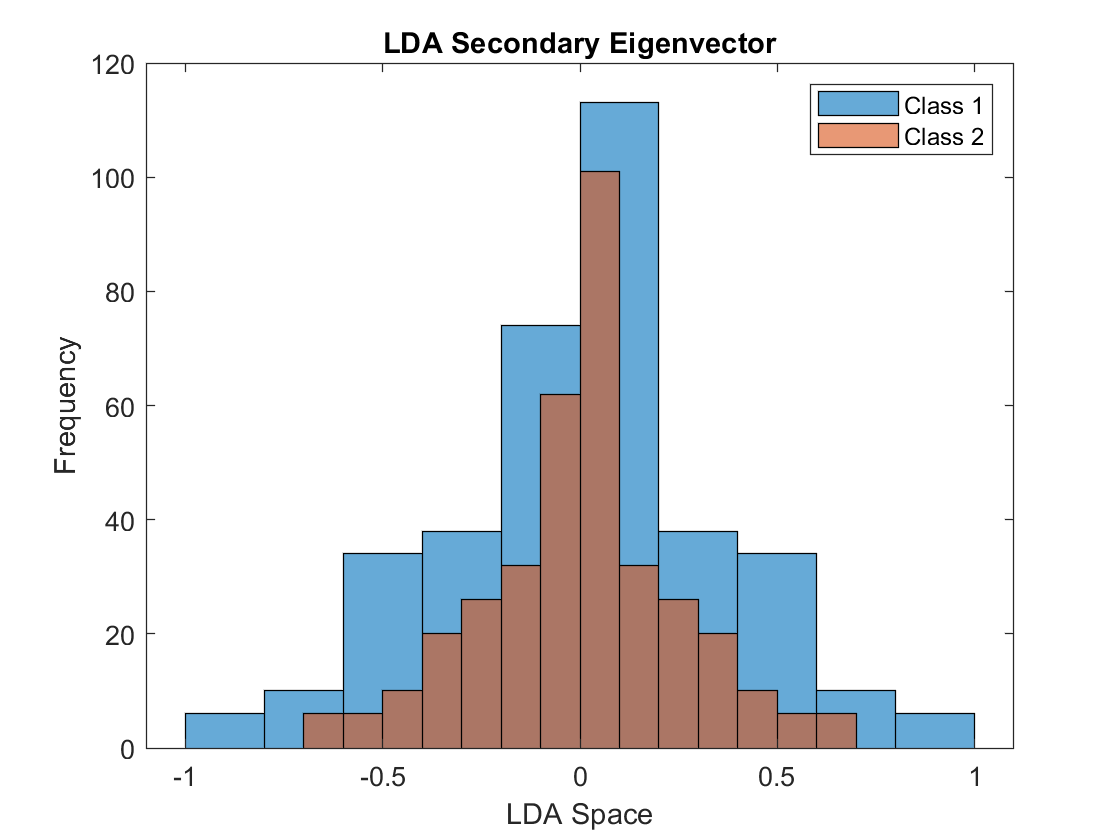

figure()

histogram(tr(pos,2))
hold on
histogram(tr(neg,2))
title('LDA '+type+' Eigenvector')
xlabel('LDA Space')
ylabel('Frequency')
legend('Class 1','Class 2')
saveas(gcf,'P1\LDA2_Histogram_'+type+'.jpg')